## Load functions

% this file should be in the same directory as the /functions dir
% restoredefaultpath;
addpath(['~/Documents/Courses/'...
    'ELEC-E5620 Audio Signal Processing/'...
    'Demo_FVN/matlab/functions']);

# Schroeder Comb-Allpass

clear all;

N = 1000;
X = [1; zeros(N-1,1)]; % input: impulse
g = 0.8;               % feedforward/back gain coefficient
d = 131;               % delay in samples
Y = schrdAllpass(X, g, d)

#### Plot

figure()
stem(X, 'filled', 'DisplayName', 'input'); hold on;
stem(Y, 'DisplayName', 'output'); hold off;
xlim([-15 N+15]); xlabel('samples');
ylim([-1.05 1.05]); ylabel('amplitude [linear]');
legend()
title('Schroeder Comb-Allpass')
ylabel('amplitude')
xlabel('sample')

#### Listen

soundsc(Y+X, 44100); % mixed with input to hear combing

# Velvet Noise Generator

clear all;

N = 4100;   % sequence length
f = 83;     % frequency (pulse density) in Hz
Fs = 44100; 

Y = velvet(N, f, Fs);

#### Plot

NOTE: Double check your signal size—long signals take a while!

Td = Fs/f;          % pulse period
nPulse = N/Td;      % number of pulses in the sequence

% plot the generated signal
stem(Y, 'filled', 'LineWidth', 1); hold on;

% plot the segment bounds
segBounds = [1:nPulse] * Td;
for i=1:length(segBounds)
    xline(segBounds(i), '--r', 'LineWidth', 0.5);
end
xlabel('samples')
ylabel('amplitude')
legend('VN sequence', 'period boundaries')
axis tight
ylim([-1 1]*1.05)
hold off;

#### Listen

soundsc(Y, 44100)

# Segmentation

#### Uniform segmentation

# Plot FFT

- Note: **fftshift()** shifts bins to put 0Hz at the center (odd N) or center +1 (even N)

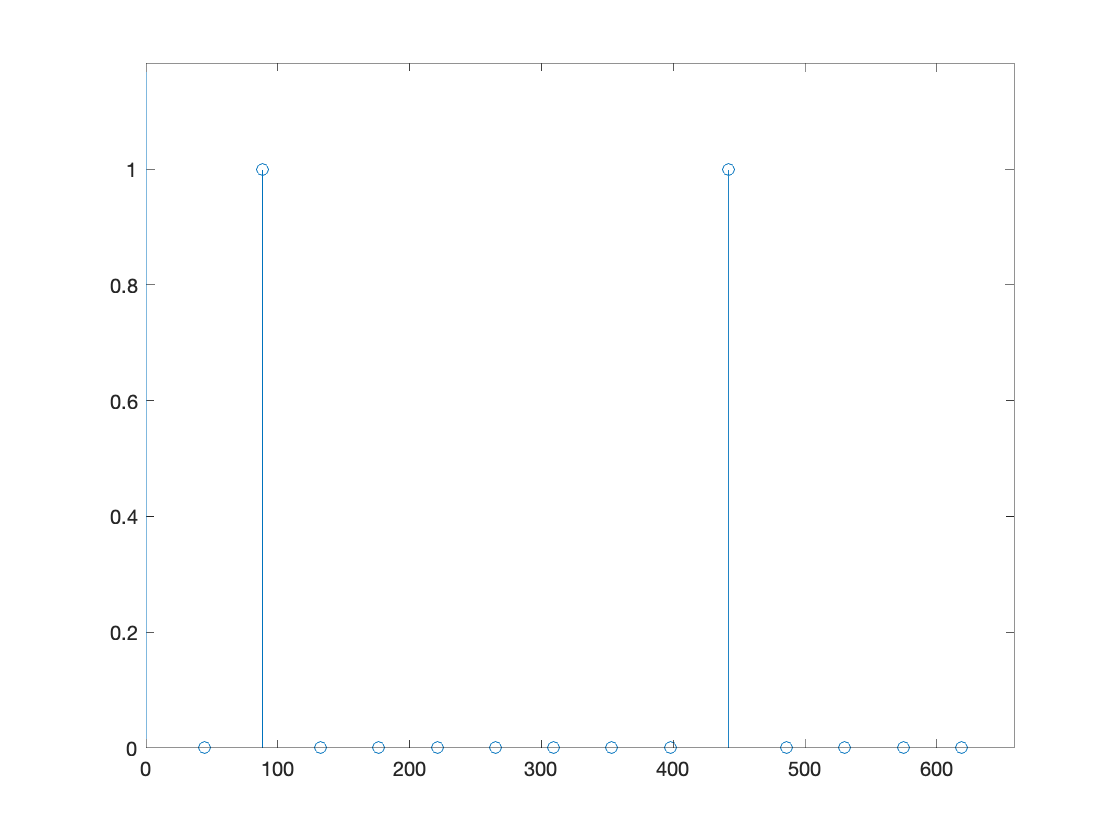

signal = X;
Fs = 44100;
zoom = [0 Fs/2];         % "zoom in" on this freq range

N = length(signal);
H = fft(signal, N);
mag = abs(H)*2/N;
mag = fftshift(mag);    

% the plot indices of freqbins (of fftshift'd spectrum)
pidx = (floor(N/2)+1:N); % spectrum 0 -> Nyquist
mag = mag(pidx);
f = linspace(0, Fs/2, length(mag));

stem(f, mag);
% semilogx(f, mag);
xlim(zoom);              % zoom via plot limits

# Test Signal

#### Generate a test signal: tone complex

N = 1000;                   % signal size
Fs = 44100;
Fc = [0 100 4000 Fs/2];      % frequencies to form complex tone DC...Nyq
% Fc = Fs/N .* [0 2 10 N/2] % alternatively...easier to place at specific freq bins

Fc = 	1.0e+04 *

         0    0.0088    0.0441    2.2050


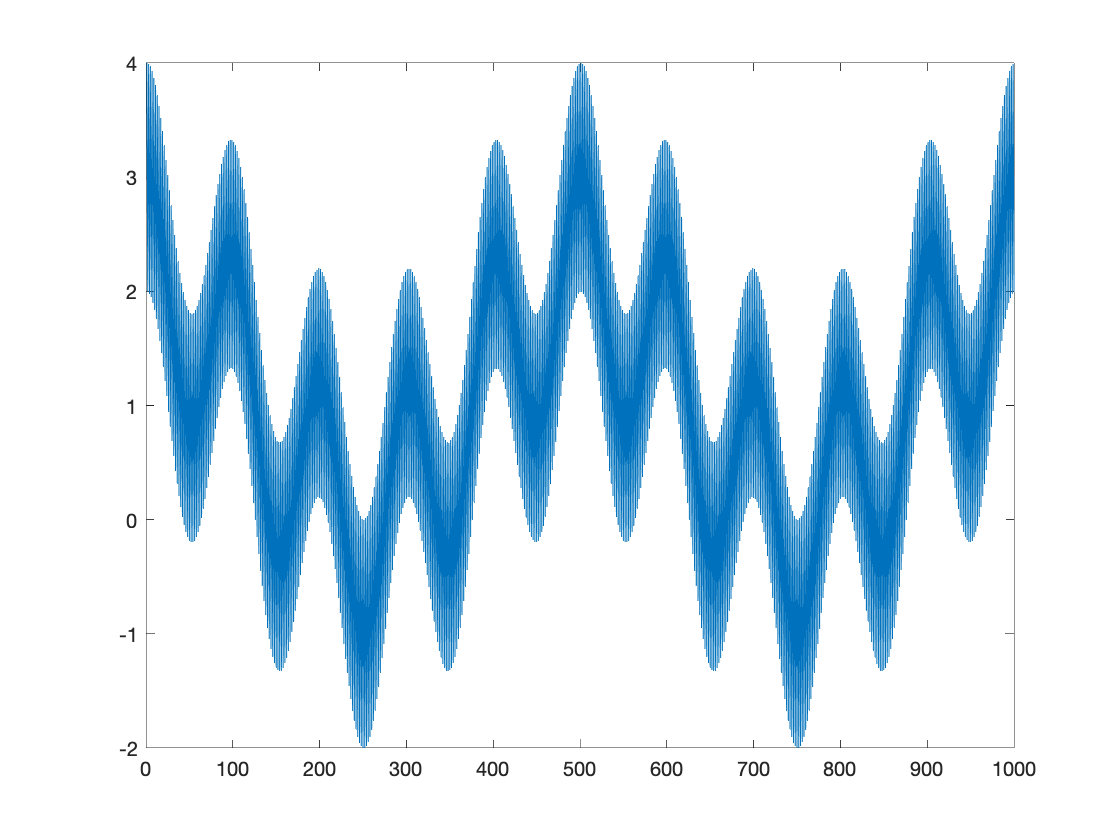

    
t = linspace(0,N-1,N)/Fs;    % normalized time indices
% dt = N/Fs;

X = sum(cos(2*pi.*Fc.*t'), 2);
% X = X / max(abs(X));        % normalize the signal
plot(X)